# Global params

prefix = '1222';
bmp_path = './BMP/';
pixelSize = 0.6; % in um
levels = 256;

xCellSize = 50; % in um
yCellSize = 50; % in um
xSepSize = 50; % in um
ySepSize = 50; % in um

# Gen BMP from linear pattern

## Basic param

period_list = [3.6 10 100]; % in um
offset_list = [0,20,40]; % in levels
Ny = round(yCellSize/pixelSize);

## Gen Linear pattern

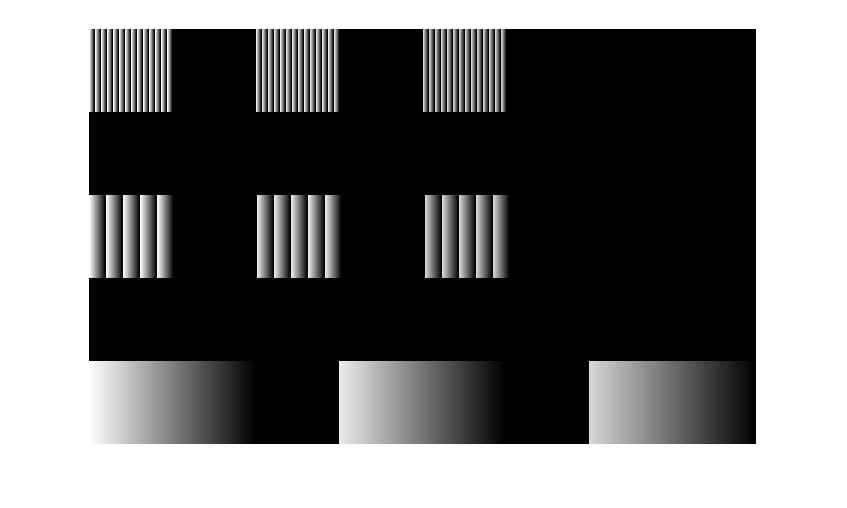


for ii = 1:length(period_list)
    Period = period_list(ii);
    % horizontal arrangement
    for nn = 1:length(offset_list)
        offset = offset_list(nn);
        % Linear pattern
        tmp = uint8(linspace(offset,levels-1,round(Period/pixelSize)));
        
        tmp = levels-1 - tmp;
        Nx = ceil(xCellSize/Period);
        tmp = repmat(tmp,1,Nx);
        if nn==1
            I = tmp;
        else
            I = [I,zeros(1,round(xSepSize/pixelSize)),tmp];
        end
    end
    I = repmat(I,Ny,1);
    % vertical stacking
    if ii==1
        I_tot = I;
    else
        if size(I,2)>size(I_tot,2)
            I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));...
                zeros(round(ySepSize/pixelSize),size(I,2)); I];
        else
            I_tot = [I_tot;...
                zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
        end
    end
end

imwrite(I_tot, [bmp_path,prefix,'-lin.bmp']);
imshow(I_tot)

disp( [bmp_path,prefix,'-lin.bmp'])

./BMP/1222-lin.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 400.2 x 249.0 um


# Gen BMP from Step pattern

## Basic param

step_list = [1,2,5]; % in pixels
offset_list = [0]; % in levels

Ny = round(yCellSize/pixelSize);

## Gen Step pattern

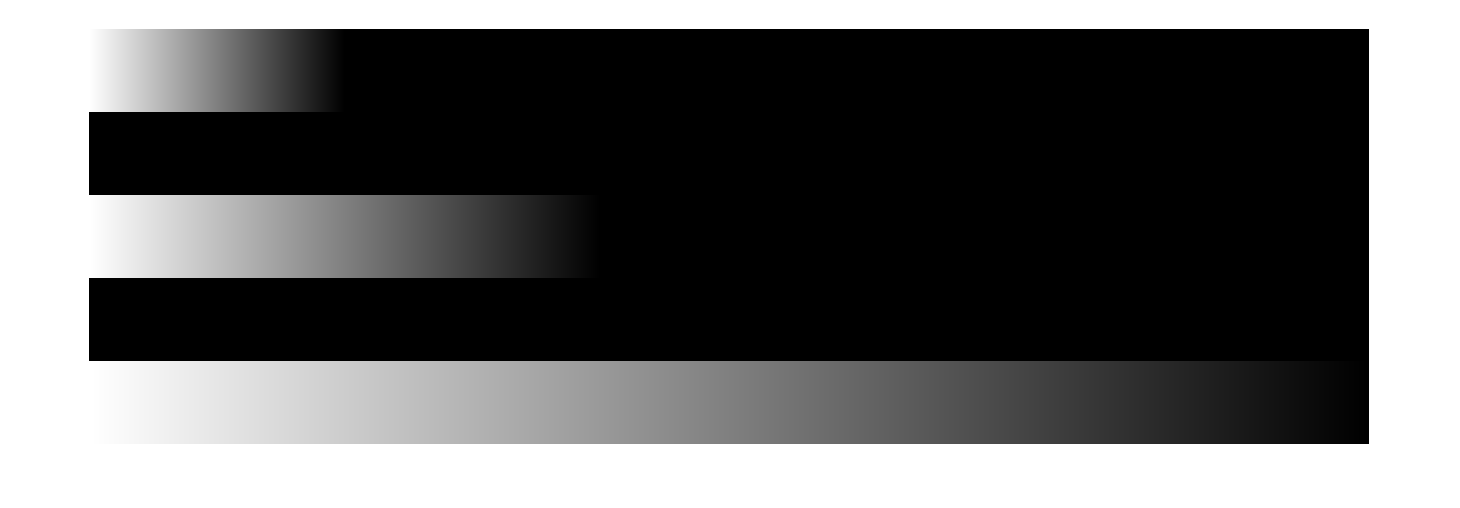


for ii = 1:length(period_list)
    Step = step_list(ii);
    % horizontal arrangement
    for nn = 1:length(offset_list)
        offset = offset_list(nn);
        % Step pattern
        tmp = uint8(kron(offset:1:(levels-1), ones(1,Step)));
        tmp = levels-1 - tmp;
        Nx = ceil(xCellSize/length(tmp));
        tmp = repmat(tmp,1,Nx);
        if nn==1
            I = tmp;
        else
            I = [I,zeros(1,round(xSepSize/pixelSize)),tmp];
        end
    end
    I = repmat(I,Ny,1);
    % vertical stacking
    if ii==1
        I_tot = I;
    else
        if size(I,2)>size(I_tot,2)
            I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));...
                zeros(round(ySepSize/pixelSize),size(I,2)); I];
        else
            I_tot = [I_tot;...
                zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
        end
    end
end

imwrite(I_tot, [bmp_path,prefix,'-step.bmp']);
imshow(I_tot)

disp( [bmp_path,prefix,'-lin.bmp'])

./BMP/1222-lin.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 768.0 x 249.0 um


# Gen BMP from stucture

## Basic param

xCellSize = 20; % in um
yCellSize = 20; % in um
xSepSize = 100; % in um
Ny = round(yCellSize/pixelSize);

## Gen BMP file

xSize = 300; % in um
% 读取
file_list = ls('gt_*.mat');
% 写入
I_tot = [];
for kk = 1:size(file_list,1)
    % load file
    load(file_list(kk,:));
    % gen cell
    I = repmat(x,Ny,1);
    Nx = ceil(xCellSize/(pixelSize*length(x)));
    I = repmat(I,1,Nx);
    I = uint8(round(I));
    % vertical stacking
    if size(I,2)>size(I_tot,2)
        I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));I];
    else
        I_tot = [I_tot;I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
    end
end
imwrite(I_tot, [bmp_path,prefix,num2str(kk,'%02d'),'.bmp']);

# Merge BMPs

## Basic param

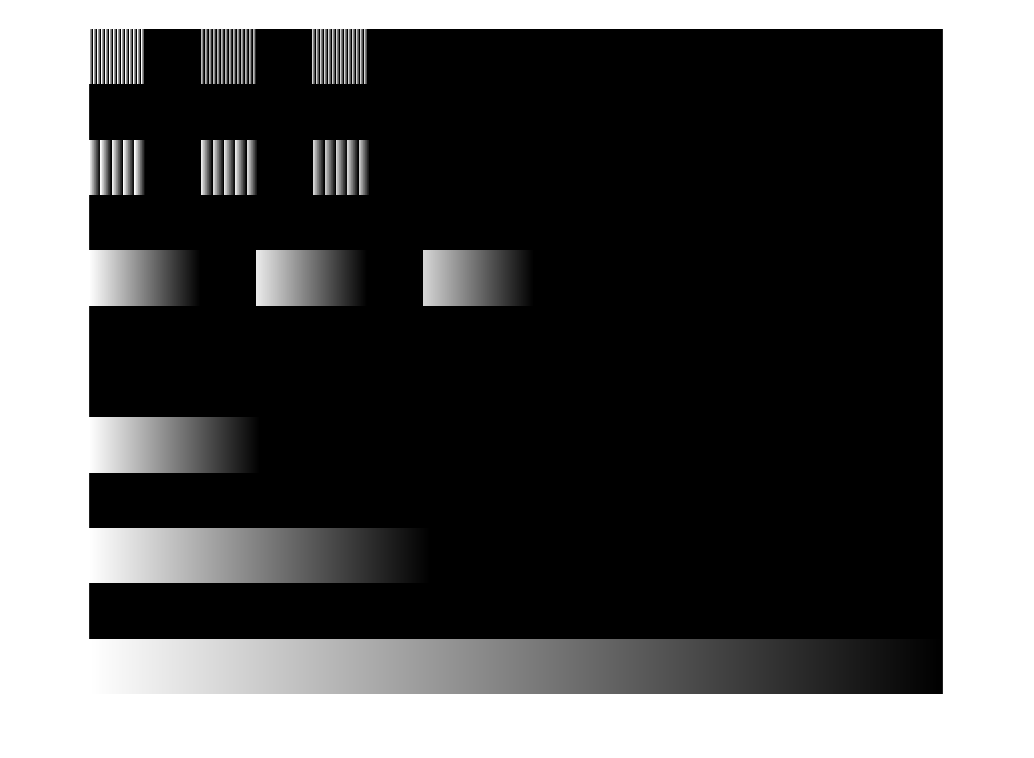

ySepSize = 100; % in um
try
    delete([bmp_path,prefix,'-merged.bmp'])
end
bmp_list = ls([bmp_path,prefix,'*.bmp']);
for kk = 1:size(bmp_list,1)
    % load file
    I = imread([bmp_path,bmp_list(kk,:)]);
    % vertical stacking
    if kk==1
        I_tot = I;
    else
        if size(I,2)>size(I_tot,2)
            I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));...
                zeros(round(ySepSize/pixelSize),size(I,2)); I];
        else
            I_tot = [I_tot;...
                zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
        end
    end
end
imwrite(I_tot, [bmp_path,prefix,'-merged.bmp']);
imshow(I_tot)

disp( [bmp_path,prefix,'-merged.bmp'])

./BMP/1222-merged.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 768.0 x 598.2 um
